# Project2 : Motion detection via communication signals

涂峻绫(12213010), 欧阳莹轩(12212961), 肖星辰(12212904), 欧阳安男(12211831)

## Introduction

## Results and Analysis

### Task 1

- For the reference signal and the surveillance signal, draw their time domain waveforms and their frequency domain waveforms.

Initialize and load audio to $ref$ and $sur$.

clear;clc;
load('proj2/data_1.mat');
t = 1/f_s : 1/f_s : 0.5;
t_ms = t*1000;
ref = seq_ref;
sur = seq_sur;

Do Digital Down Convert (DDC).

f_ddc = -3e6;
ref_ddc = ref .* exp(-1i * 2*pi * f_ddc * t);
sur_ddc = sur .* exp(-1i * 2*pi * f_ddc * t);

Do Low Pass Filter (LPF).

f_cutoff = 9e6;
[b,a] = butter(24, f_cutoff/(f_s/2));
ref_lpf = filter(b, a, ref_ddc);
sur_lpf = filter(b, a, sur_ddc);

Calculate spectrum.

freq_mhz = 2110-2123+2e-6 : 2e-6 : 2135-2123;
sur_freq = abs(fftshift(fft(sur)));
sur_ddc_freq = abs(fftshift(fft(sur_ddc)));
sur_lpf_freq = abs(fftshift(fft(sur_lpf)));
ref_freq = abs(fftshift(fft(ref)));
ref_ddc_freq = abs(fftshift(fft(ref_ddc)));
ref_lpf_freq = abs(fftshift(fft(ref_lpf)));

Convert to dB.

ref_freq = 20 * log10(ref_freq / max(sur_freq));
ref_ddc_freq = 20 * log10(ref_ddc_freq / max(sur_ddc_freq));
ref_lpf_freq = 20 * log10(ref_lpf_freq / max(sur_lpf_freq));
sur_freq = 20 * log10(sur_freq / max(sur_freq));
sur_ddc_freq = 20 * log10(sur_ddc_freq / max(sur_ddc_freq));
sur_lpf_freq = 20 * log10(sur_lpf_freq / max(sur_lpf_freq));

Plot.

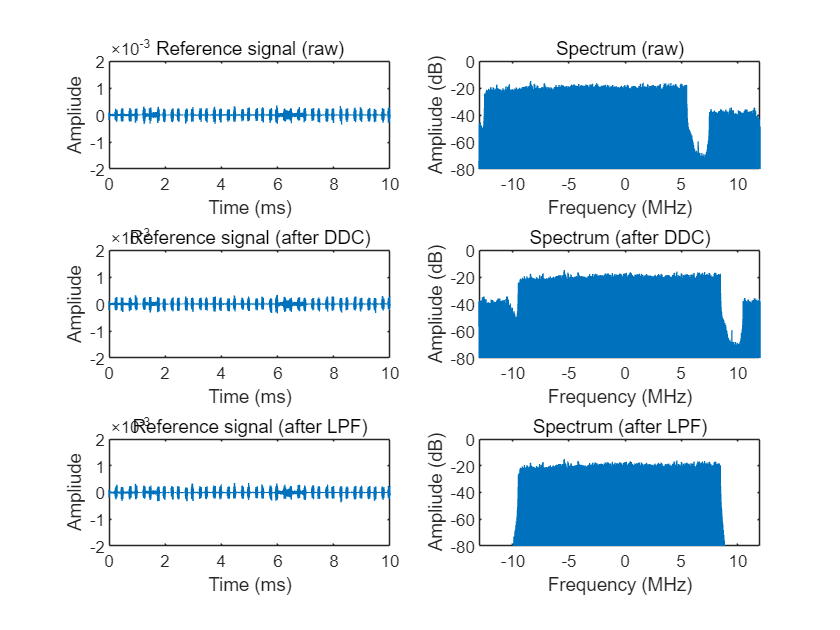

figure;
task1plot(1, 'Reference signal (raw)', t_ms, real(ref), true);
task1plot(3, 'Reference signal (after DDC)', t_ms, real(ref_ddc), true);
task1plot(5, 'Reference signal (after LPF)', t_ms, real(ref_lpf), true);
task1plot(2, 'Spectrum (raw)', freq_mhz, ref_freq, false);
task1plot(4, 'Spectrum (after DDC)', freq_mhz, ref_ddc_freq, false);
task1plot(6, 'Spectrum (after LPF)', freq_mhz, ref_lpf_freq, false);

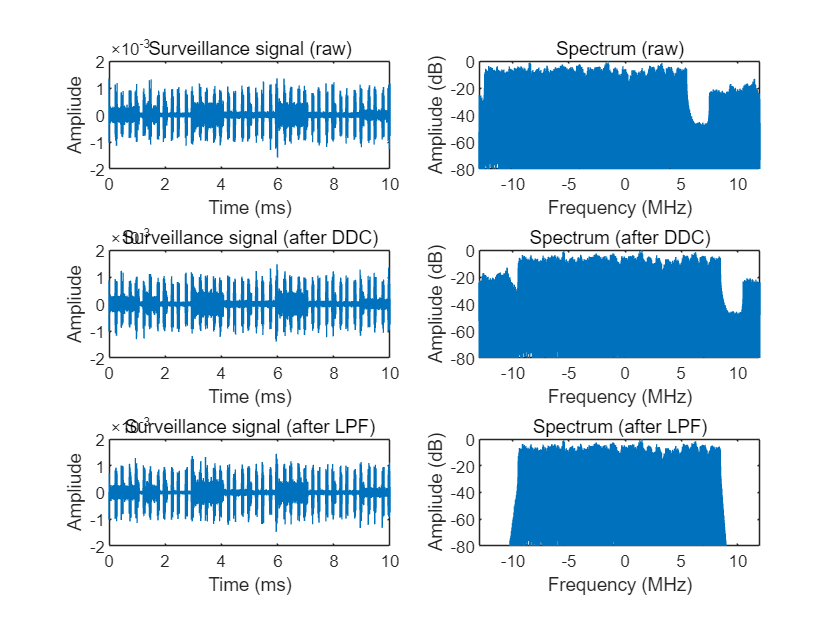

figure;
task1plot(1, 'Surveillance signal (raw)', t_ms, real(sur), true);
task1plot(3, 'Surveillance signal (after DDC)', t_ms, real(sur_ddc), true);
task1plot(5, 'Surveillance signal (after LPF)', t_ms, real(sur_lpf), true);
task1plot(2, 'Spectrum (raw)', freq_mhz, sur_freq, false);
task1plot(4, 'Spectrum (after DDC)', freq_mhz, sur_ddc_freq, false);
task1plot(6, 'Spectrum (after LPF)', freq_mhz, sur_lpf_freq, false);

#### Description

### Task 2

- Plot the Range Doppler spectrum of the signal located at 0-0.5s, 2-2.5s, 5-5.5s and 7-7.5s.

Initialize the light speed $c$ and the range of $\tau$ and $f_D$.

clear;clc;
light_speed = 3e8;
tau = 0 : 12/light_speed : 72/light_speed;
fd = -40:2:40;

Calculate the $cor$ for every $\tau$ and $f_D$ in range, and plot them in the images of Range-Doppler Spectrum.

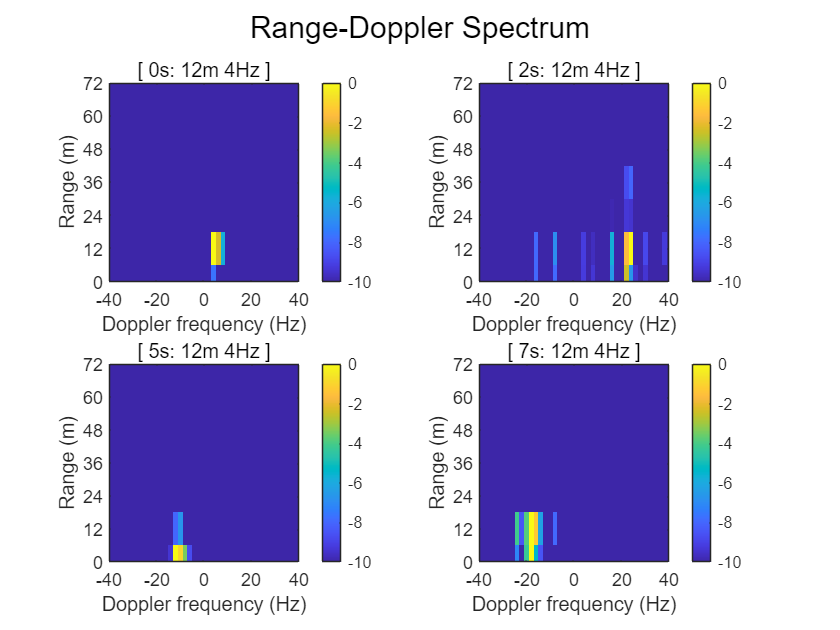

figure;
sgtitle('Range-Doppler Spectrum');
load('proj2/data_1.mat');
sur = ddc_lpf(seq_sur, -3e6, 9e6, f_s, 0.5);
ref = ddc_lpf(seq_ref, -3e6, 9e6, f_s, 0.5);
cor1 = Cor(tau, fd, 0.5, 125e5, sur, ref);
Draw_task2(tau, fd, cor1, 1, 0.0);
load('proj2/data_5.mat');
sur = ddc_lpf(seq_sur, -3e6, 9e6, f_s, 0.5);
ref = ddc_lpf(seq_ref, -3e6, 9e6, f_s, 0.5);
cor2 = Cor(tau, fd, 0.5, 125e5, sur, ref);
Draw_task2(tau, fd, cor2, 2, 2.0);
load('proj2/data_11.mat');
sur = ddc_lpf(seq_sur, -3e6, 9e6, f_s, 0.5);
ref = ddc_lpf(seq_ref, -3e6, 9e6, f_s, 0.5);
cor3 = Cor(tau, fd, 0.5, 125e5, sur, ref);
Draw_task2(tau, fd, cor3, 3, 5.0);
load('proj2/data_15.mat');
sur = ddc_lpf(seq_sur, -3e6, 9e6, f_s, 0.5);
ref = ddc_lpf(seq_ref, -3e6, 9e6, f_s, 0.5);
cor4 = Cor(tau, fd, 0.5, 125e5, sur, ref);
Draw_task2(tau, fd, cor4, 4, 7.0);

#### Description

### Task 3

- Plot the T ime Doppler spectrum with coherent integration time (CIT) equal to 0.5s. Time range is 0-9.5s.

Initialize the light speed $c$, time range $time$ and the range of $\tau$ and $f_D$.

clear;clc;
light_speed = 3e8;
tau = 0 : 12/light_speed : 72/light_speed;
fd = -40:2:40;
time = 0:0.5:9.5;

Calculate the $cor$ for every  $f_D$ in range and for $\tau$ which makes $cor$ gets the maximum.

g = zeros(length(time),length(fd));
for data_index = 1:20
   load("proj2/data_"+data_index+".mat");
   sur = ddc_lpf(seq_sur, -3e6, 9e6, f_s, 0.5);
   ref = ddc_lpf(seq_ref, -3e6, 9e6, f_s, 0.5);

   cor = Cor_fft(tau, fd, 0.5, 125e5, sur, ref);
   corMax = max(max(cor));
   [tauMax_index, ~] = find(corMax==cor);
   cor_relative = 10.*log(cor./max(cor(tauMax_index,:)));
   g(data_index,:) = cor_relative(tauMax_index,:);
end

Plot them in the images of Time-Doppler Spectrum. Time range holds for 0.0s-9.5s.

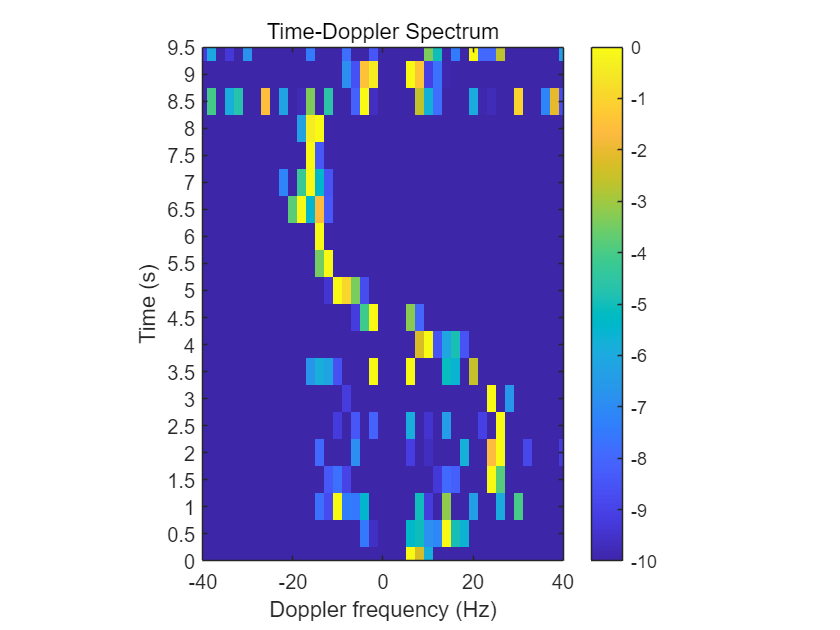

figure;
img = imagesc(fd, time, real(g));
clim([-10 0]);
colorbar
set(gca,'Ydir','normal');
title("Time-Doppler Spectrum");
xlabel("Doppler frequency (Hz)");
ylabel("Time (s)");
axis([-40 40 0.0 9.5]);
xticks(-40:20:40);
yticks(0.0:0.5:9.5);
img.Parent.DataAspectRatio = [12 1 1];

#### Description

### Enhencement

#### Task 2

- In this part, we calculate the $cor$ by the help of $DFT$ to enhance.

Initialize the light speed $c$ and the range of $\tau$ and $f_D$.

clear;clc;
light_speed = 3e8;
tau = 0 : 12/light_speed : 72/light_speed;
fd = -40:2:40;

Calculate the $cor$ for every $\tau$ and $f_D$ in range, and plot them in the images of Range-Doppler Spectrum.

figure;
sgtitle('Range-Doppler Spectrum');
load('proj2/data_1.mat');
tic;
sur = ddc_lpf(seq_sur, -3e6, 9e6, f_s, 0.5);
ref = ddc_lpf(seq_ref, -3e6, 9e6, f_s, 0.5);
cor1 = Cor(tau, fd, 0.5, 125e5, sur, ref);
toc;

历时 86.346327 秒。


Draw_task2(tau, fd, cor1, 1, 0.0);
tic;
cor1 = Cor_fft(tau, fd, 0.5, 125e5, sur, ref);
toc;

历时 7.875763 秒。


Draw_task2(tau, fd, cor1, 2, 0.0);
load('proj2/data_5.mat');
tic;
sur = ddc_lpf(seq_sur, -3e6, 9e6, f_s, 0.5);
ref = ddc_lpf(seq_ref, -3e6, 9e6, f_s, 0.5);
cor2 = Cor(tau, fd, 0.5, 125e5, sur, ref);
toc;

历时 86.533992 秒。


Draw_task2(tau, fd, cor2, 3, 0.0);
tic;
cor2 = Cor_fft(tau, fd, 0.5, 125e5, sur, ref);
toc;

历时 8.487225 秒。


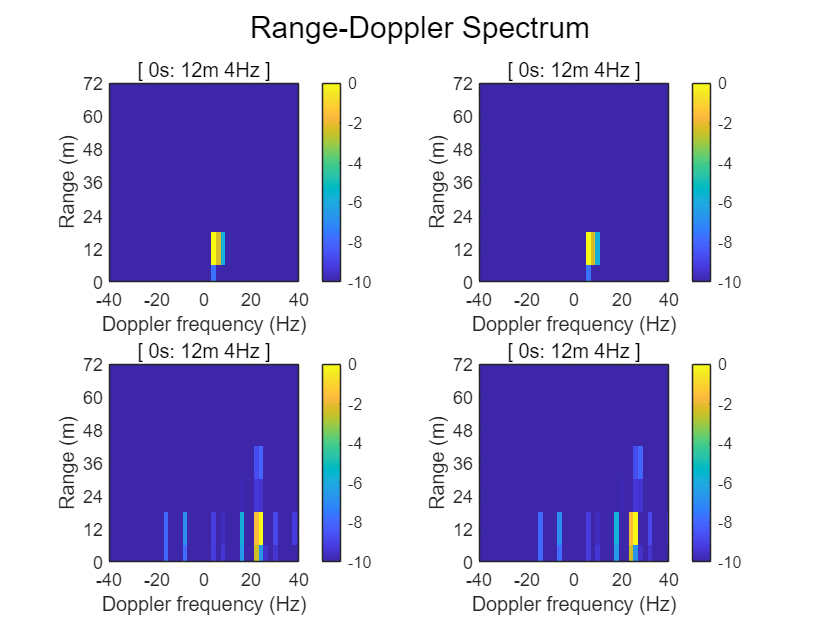

Draw_task2(tau, fd, cor2, 4, 0.0);

By using $fft$, we can save as much as 10 times of time to calculate the $cor$, and they have the same effect.

#### Task 2

- In this part, we try to abandon the filter of Digital Down Convert (DDC) and  Low-Pass Filter (LPF), to order to discuss the effrct of them.

Initialize the light speed $c$ and the range of $\tau$ and $f_D$.

clear;clc;
light_speed = 3e8;
tau = 0 : 12/light_speed : 72/light_speed;
fd = -40:2:40;

Calculate the $cor$ for every $\tau$ and $f_D$ in range, and plot them in the images of Range-Doppler Spectrum.

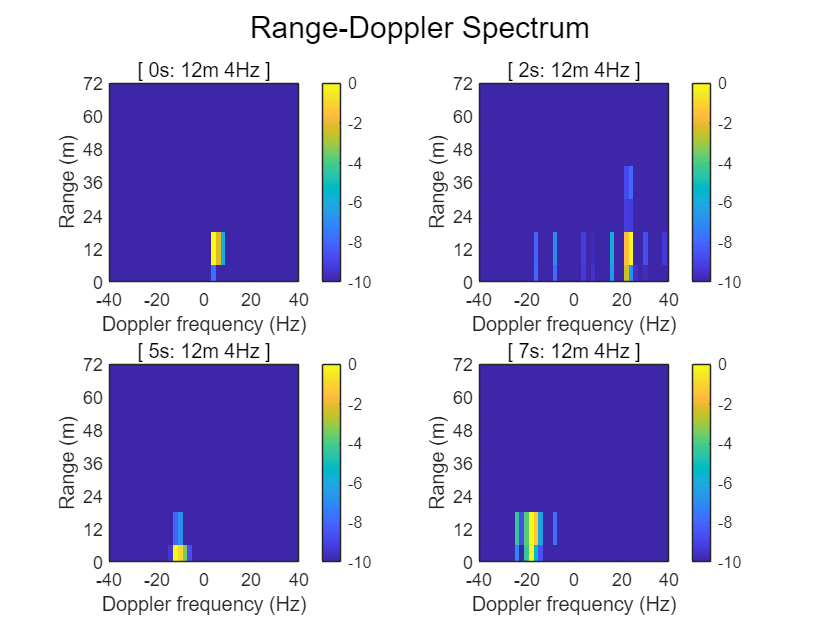

figure;
sgtitle('Range-Doppler Spectrum');
load('proj2/data_1.mat');
cor1 = Cor(tau, fd, 0.5, 125e5, seq_sur, seq_ref);
Draw_task2(tau, fd, cor1, 1, 0.0);
load('proj2/data_5.mat');
cor2 = Cor(tau, fd, 0.5, 125e5, seq_sur, seq_ref);
Draw_task2(tau, fd, cor2, 2, 2.0);
load('proj2/data_11.mat');
cor3 = Cor(tau, fd, 0.5, 125e5, seq_sur, seq_ref);
Draw_task2(tau, fd, cor3, 3, 5.0);
load('proj2/data_15.mat');
cor4 = Cor(tau, fd, 0.5, 125e5, seq_sur, seq_ref);
Draw_task2(tau, fd, cor4, 4, 7.0);

Comparing to the images of task 2, we can tell that the Digital Down Convert (DDC) and  Low-Pass Filter (LPF) have little effect in finding the fittest $\tau$ and $f_D$.

#### Task 3

- In this part, we try to set coherent integration time (CIT) as 0.1s.

Initialize the light speed $c$, time range $time$ and the range of $\tau$ and $f_D$.

clear;clc;
light_speed = 3e8;
tau = 0 : 12/light_speed : 72/light_speed;
fd = -40:2:40;
time = 0:0.5:9.5;

Calculate the $cor$ for every  $f_D$ in range and for $\tau$ which makes $cor$ gets the maximum.

g = zeros(length(time),length(fd));
for data_index = 1:20
   load("proj2/data_"+data_index+".mat");
   for div_time = 1:5
       cor = Cor_fft(tau, fd, 0.5, 125e5, seq_sur(1+length(seq_sur)/5*(div_time-1):length(seq_sur)/5*div_time), seq_ref(1+length(seq_sur)/5*(div_time-1):length(seq_sur)/5*div_time));
       tauMax_index = 1;
       corMax = cor(1);
       for index_tau = 1:length(tau)
           for index_fd = 1:length(fd)
               if corMax < cor(index_tau, index_fd)
                   corMax = cor(index_tau, index_fd);
                   tauMax_index = index_tau;
               end
           end
       end
       corMax = max(max(cor));
       cor_relative = 10.*log(cor./corMax);
       g((data_index-1)*5+div_time,:) = cor_relative(tauMax_index,:);
   end
end

Plot them in the images of Time-Doppler Spectrum. Time range holds for 0.0s-9.5s.

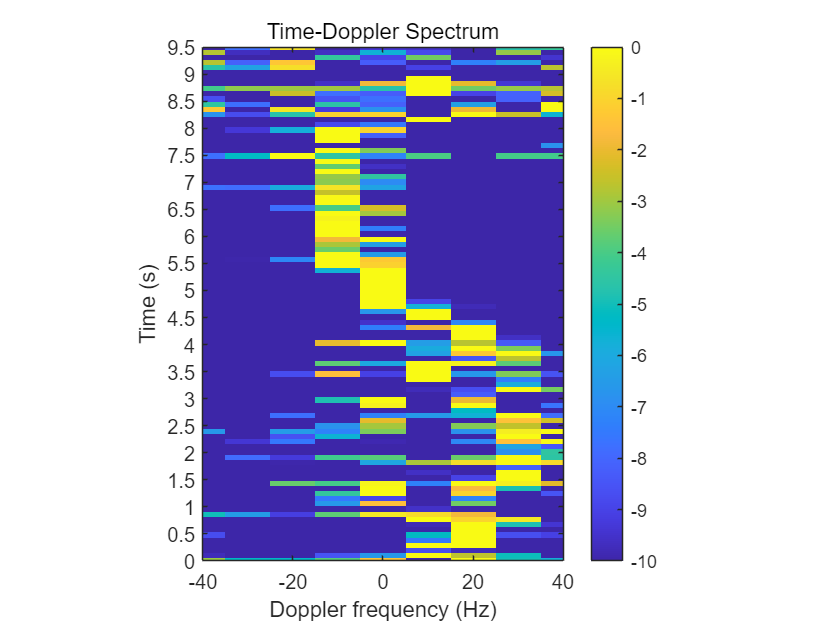

figure;
img = imagesc(fd, time, real(g));
clim([-10 0]);
colorbar
set(gca,'Ydir','normal');
title("Time-Doppler Spectrum");
xlabel("Doppler frequency (Hz)");
ylabel("Time (s)");
axis([-40 40 0.0 9.5]);
xticks(-40:20:40);
yticks(0.0:0.5:9.5);
img.Parent.DataAspectRatio = [12 1 1];

From the image, we can tell that, since the CIT becomes 0.1s, the $f_D$ affects less, that is, with a more accurate CIT, we can get a less accurate $f_D$.

### Functions

The function to plot in task1.

function task1plot(plot_idx, title_name, x, y, is_t_domain)
subplot(3, 2, plot_idx);
plot(x, y);
title(title_name);
if is_t_domain
    xlabel('Time (ms)');
    ylabel('Ampliude');
    axis([0 10 -2e-3 2e-3]);
    xticks(0:2:10);
    yticks((-2:2)*1e-3);
else
    xlabel('Frequency (MHz)');
    ylabel('Ampliude (dB)');
    axis([-13 12 -80 0]);
    yticks(-80:20:0);
end
end

Function to get a signal through Digital Down Convert (DDC) and  Low-Pass Filter (LPF).

function res = ddc_lpf(sig, f_ddc, f_cutoff, fs, T)
t = 1/fs :1/fs : T;
[b, a] = butter(24, f_cutoff/(fs/2));
sig_ddc = sig .* exp(-1i * 2*pi * f_ddc *t);
res = filter(b, a, sig_ddc);
end

Function to $Cor(\tau, f_D, t_0)$

function cor = Cor(tau, fd, T, N, seq_sur, seq_ref)
cor = zeros(length(tau),length(fd));
Ts = T/N;
fs = 1/Ts;
for index_tau = 1:length(tau)
    for index_fd = 1:length(fd)
        if(tau(index_tau) == 0)
            ref_shift = conj(seq_ref);
            sur_shift = seq_sur;
        else
            shift = round(tau(index_tau)/Ts);
            ref_shift = conj([ zeros(1,shift), seq_ref ]);
            sur_shift = [ seq_sur, zeros(1,shift)];
        end
        cor(index_tau,index_fd) = sum( sur_shift .* ref_shift .* exp(-1i*2*pi*(fd(index_fd)/fs)*(0:length(ref_shift)-1)) );
    end
end

cor = cor.*Ts;
end

Function enhanced to $Cor(\tau, f_D, t_0)$ by using $fft$.

function cor = Cor_fft(tau, fd, T, N, seq_sur, seq_ref)
cor = zeros(length(tau),length(fd));
Ts = T/N;
fs = 1/Ts;
for index_tau = 1:length(tau)
    offset = round(tau(index_tau)/Ts);
    
    y = [seq_sur, zeros(1,offset)] .* [zeros(1,offset), conj(seq_ref)];

    fft_y = fftshift(fft(y));
    indices = round(length(seq_sur).*fd/fs + length(seq_sur)/2);
    cor(index_tau,:) = fft_y(1,indices);
end
end

Function draw Range-Doppler Spectrum for task2.

function Draw_task2(tau, fd, cor, pic_index, time_start)
corMax = max(max(cor));
cor_relative = 10.*log(cor./corMax);

light_speed = 3e8;
subplot(2,2,pic_index)
imagesc(fd, tau*light_speed, real(cor_relative));
clim([-10 0]);
colorbar
set(gca,'Ydir','normal');
title("[ "+time_start+"s: 12m 4Hz ]");
xlabel("Doppler frequency (Hz)");
ylabel("Range (m)");
axis([-40 40 0 72]);
xticks(-40:20:40);
yticks(0:12:72);
end

### Summary

## Expeience

........................